% distr = [0 0; 1 2; 2 4;5 7;3.5 3.5; 4.5 6]
% distr(:,1) = distr(:,1) - mean(distr(:,1));
% distr(:,2) = distr(:,2) - mean(distr(:,2));
% distr = [1 2; 2 4; 3 6; 4 8]
clear, clc, close all;

rng(0)
distr(:,1) = randn(30,1);
distr(:,2) = 3.4 + 1.2 * distr(:,1);
distr(:,2) = distr(:,2) + 0.2*randn(size(distr(:,1)));
distr(:,1) = distr(:,1) - mean(distr(:,1));
distr(:,2) = distr(:,2) - mean(distr(:,2));
distr = sortrows(distr,1);
distr

distr =    -2.8107   -3.5637
   -1.9018   -2.2796
   -1.8596   -1.9208
   -1.7594   -2.0728
   -1.3392   -1.3605
   -0.9855   -1.0945
   -0.8553   -0.9291
   -0.7569   -0.8912
   -0.6760   -0.8212
   -0.6150   -0.6524



figure;
hold on
scatter(distr(:,1),distr(:,2))
axis equal
[coeff,scores] = pca(distr)

coeff =     0.6380    0.7701
    0.7701   -0.6380


scores =    -4.5374    0.1091
   -2.9687   -0.0101
   -2.6655   -0.2065
   -2.7186   -0.0324
   -1.9021   -0.1632
   -1.4716   -0.0606
   -1.2612   -0.0659
   -1.1692   -0.0142
   -1.0637    0.0033
   -0.8947   -0.0573


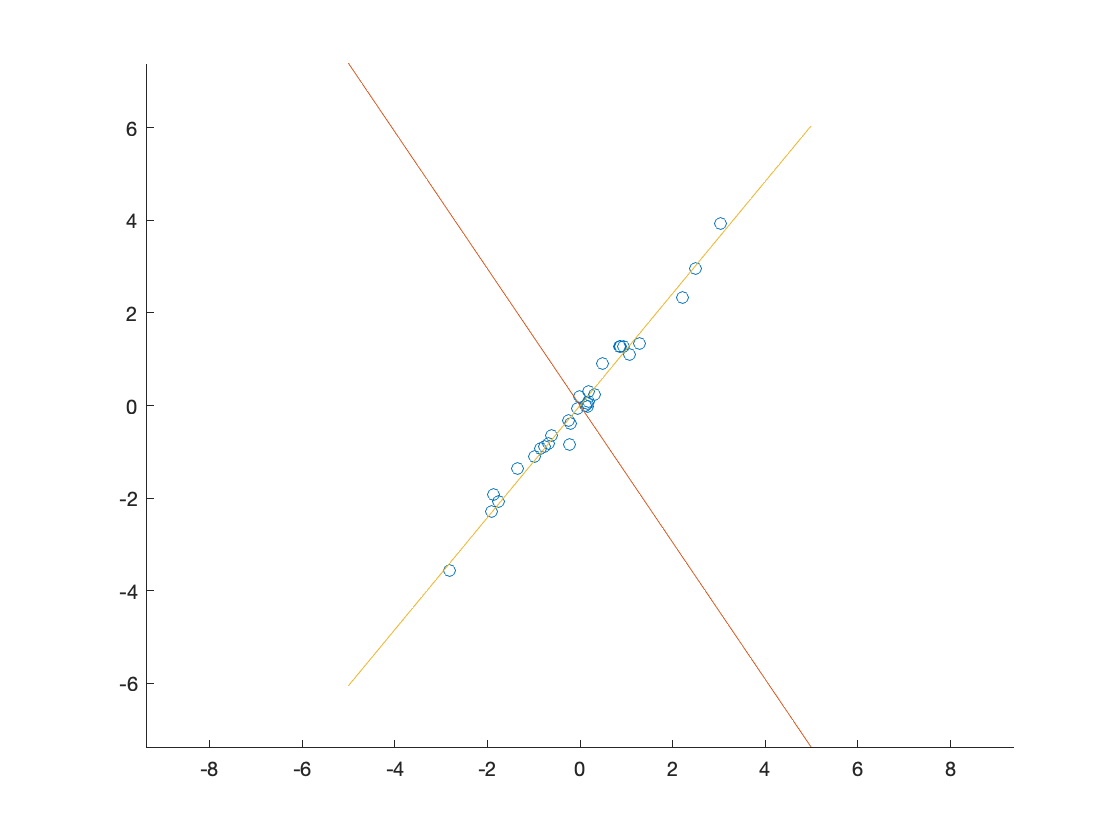

x=-5:0.1:5;
y=-1*x*distr(1,1)/distr(2,1);
y1=0.7708/0.637*x;
plot(x,y)
plot(x,y1)
hold off

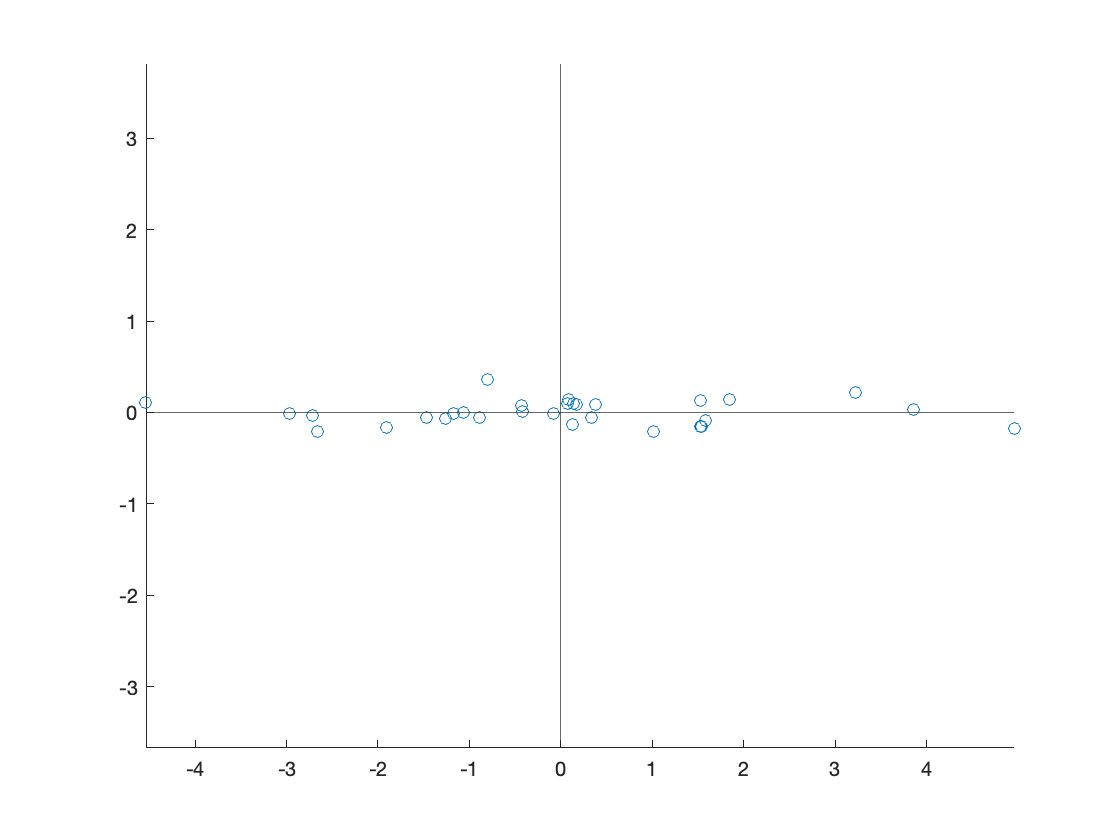


scatter(scores(:,1),scores(:,2))
xline(0)
yline(0)
axis equal

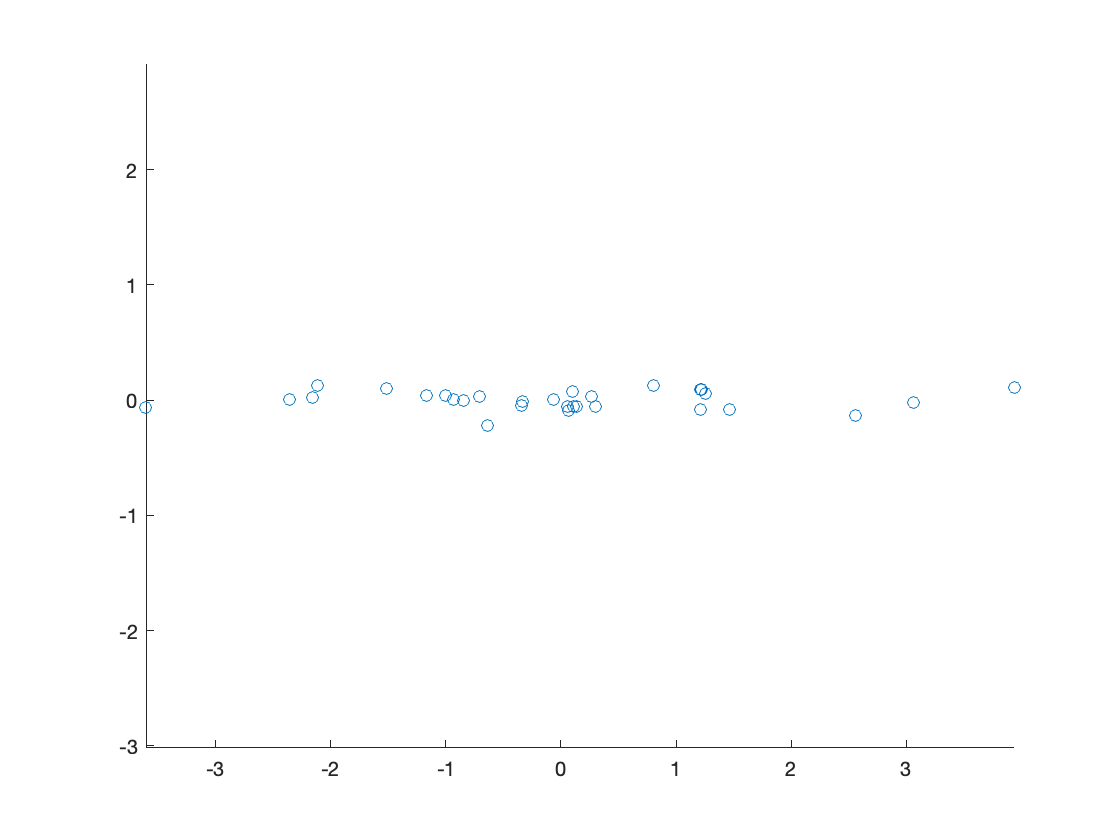


figure;
scatter(scores(:,1)*0.7936,scores(:,2)*-0.6084)
axis equal